# Moving to Pose

There are 8 points to be tested as initial points. Because our x0 = [9 5 0], and the first point already there xg = [5 5 pi/2], so the radius will be 4 for all points.

Using circle formula 


$$\begin{array}{l}
x=x_{\mathrm{goal}} \;+r\;\mathrm{cos}\;\theta \\
y=y_{\mathrm{goal}} \;+\;r\;\mathrm{sin}\;\theta 
\end{array}$$


where theta is in [0:2*pi/total_points:2*pi].

syms theta_array total_points radius_test x_goal y_goal;
radius_test  = 4;
total_points = 8;
x_goal = 5;
y_goal = 5;

%theta for every value
theta_array = [0:2*pi/(total_points-1):2*pi];

x_array = zeros(1,length(theta_array));
y_array = zeros(1,length(theta_array));

for i = 1 : length(x_array)
    x_array(i) = x_goal + radius_test*cos(theta_array(i));
    y_array(i) = y_goal + radius_test*sin(theta_array(i));
end


For the first initial point: [9, 5, pi/2]

alpha -3.141593, beta 3.141593
going backwards


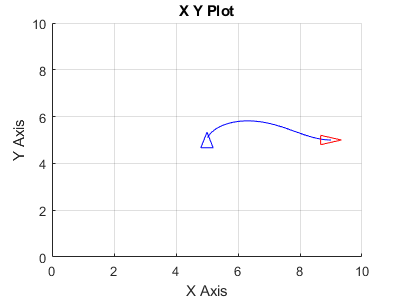

bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [x_array(1) y_array(1) 0];

r = sim('sl_drivepose');

For the second initial point: [7.4940, 8.1273, pi/2]

alpha -2.243995, beta 2.243995
going backwards


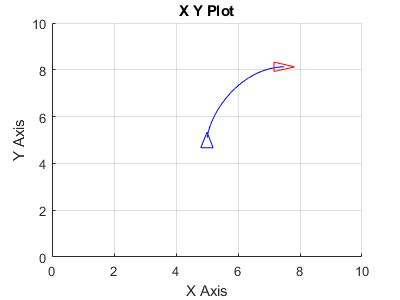

bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [x_array(2) y_array(2) 0];

r = sim('sl_drivepose');

For the third initial point: 

alpha -1.346397, beta 1.346397
going forwards


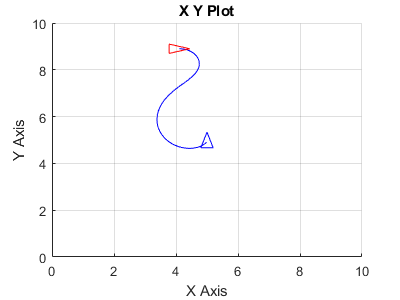

bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [x_array(3) y_array(3) 0];

r = sim('sl_drivepose');

For the fourth initial point: 

alpha 0.448799, beta -0.448799
going forwards


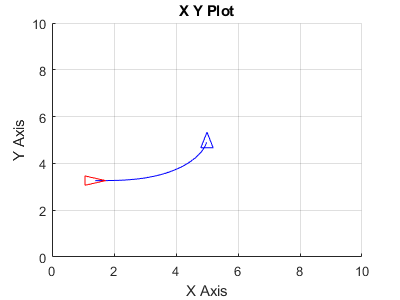

bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [x_array(4) y_array(5) 0];

r = sim('sl_drivepose');

For the fifth initial point: 

alpha 0.448799, beta -0.448799
going forwards


bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [x_array(5) y_array(5) 0];

r = sim('sl_drivepose');

For the sixth initial point: 

alpha 1.346397, beta -1.346397
going forwards


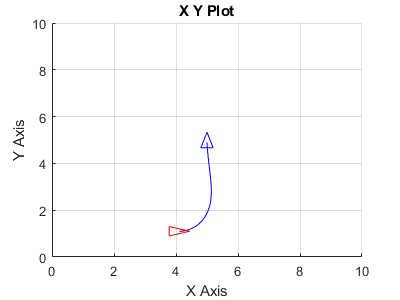

bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [x_array(6) y_array(6) 0];

r = sim('sl_drivepose');

For the seventh initial point: 

alpha 2.243995, beta -2.243995
going backwards


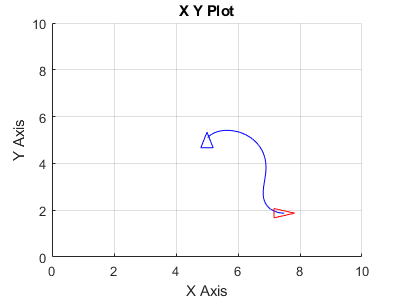

bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [x_array(7) y_array(7) 0];

r = sim('sl_drivepose');

For all the graphic above, with red triangle represent initial point and blue triangle represent goal point, we can see that the goal point is always reached for everty initial point given. Therefore the system is stable. This is because k_rho, k_alpha, and k_bheta that already determined in the sl_drivepose (the simulink file) is already satisfy the strong stability condition. With k_rho = 1, k_alpha = 5, k_bheta = -2 (you can check this in the simulink file).

## Conclusion

#### By using $k_{\rho }$ $k_{\alpha }$ $k_{\beta }$ that satisfy the strong stability condition:


$$k_{\rho } >0;k_{\beta } <0;\;k_{\alpha } +\frac{5}{3}k_{\beta } -\frac{2}{\pi }k_{\rho } >0\;\;$$


#### the system is stable.